format long

# Hausarbeit 1. Prüfungszeitraum - Zeitaufgelöste Photolumineszenz

## 1 Einleitung

*(siehe Aufgabenblatt)*

## 2 Finite Differenzen der statioären Gleichung - MHD Ammar Aljouharji

### 2.1 Lineare stationäre Gleichung

1. Der Abschnitt 8.8 wurde erarbeitet.

2.

D$\frac{\partial^2 u}{\partial z^2 }$   − ku = −s(z)            ,         $0<z<d$

$\frac{\partial u}{\partial z }$ = $\frac{u_{i+1} -u_{i-1} }{2h}$

$\frac{\partial^2 u}{\partial z^2 }$ = $\frac{u_{i+1} -{2u}_i +u_{i-1} }{h^2 }$

D $\left(\frac{u_{i+1} -{2u}_i +u_{i-1} }{h^2 }\right)$ − ku =  − $s_i$ 

($\frac{D}{h^2 }$) $u_{i-1}$ −  ($\frac{2D}{h^2 }+k$) $u_i$ + ($\frac{D}{h^2 }$) $u_{i+1}$ =  − $s_i$ 

 $a\;u_{i-1}$ −   ${e\;u}_i$ +  ${c\;u}_{i+1}$ =   $b$                  =>       $a=\frac{D}{h^2 }$      ;      $e=\frac{2D}{h^2 }+k$     ;     $c=\frac{D}{h^2 }$ ;   $b$ = ${-s}_i$

Discretize:


$$0<z<d$$
       


$$h=\frac{d-0}{N}=\frac{d}{N}$$



$$i=0,1,2,,,,,,N$$



$$Z_0 =0$$
    
$$Z_N =d$$


3.

Erste Randbedingungen :

 D $\frac{\partial u\left(0\right)}{\partial z }$= $S_L$$u\left(0\right)$

$\frac{\partial u\left(0\right)}{\partial z }$= $\frac{S_L \;u\left(0\right)}{D}$

$\frac{S_L \;u\left(0\right)}{D}$= $\frac{{\mathrm{u}}_{1\;} -u_{-1} }{2h}$

$u\left(0\right)$ = $\frac{{D\;\left(u_1 -u_{-1} \right)}_{\;} }{2h\;S_L }$

$u\left(0\right)$ = $\frac{{D\;}_{\;} }{2h\;S_L }$ $u_1$ −  $\frac{{D\;}_{\;} }{2h\;S_L }$ $u_{-1}$ 

$u_{-1}$  =  $u_1$ −  $\frac{{2h\;S_L }_{\;} }{D}$ $u\left(0\right)$ 

Zweite Randbedingungen :

 D $\frac{\partial u\left(d\right)}{\partial z }$= ${-S}_R$$u\left(d\right)$

$\frac{\partial u\left(d\right)}{\partial z }$= $\frac{{-S}_{R\;} \;u\left(d\right)}{D}$

$\frac{{-S}_{R\;} \;u\left(d\right)}{D}$ = $\frac{{\mathrm{u}}_{N+1} -u_{N-1} }{2h}$

$u\left(d\right)$ = $\frac{D\;\left({\mathrm{u}}_{N+1} -u_{N-1} \right)}{-\;2h\;S_R }$

$u\left(d\right)$ = $\frac{D\;}{-\;2h\;S_R }\;u_{N+1} -\frac{D\;}{-\;2h\;S_R }\;u_{N+1} \;$

$u_{N+1}$= $\frac{-\;2h\;S_R \;}{D}\;u\left(d\right)+\;\;u_{N-1} \;$

$u_{N+1}$= $\frac{-\;2h\;S_R \;}{D}\;u_N +\;\;u_{N-1} \;$

$i=o\Rightarrow$   $a\;u_{-1}$ −   ${e\;u}_0$ +  ${c\;u}_1$ =   $b$

 $a\left(u_1 -\frac{{2h\;S_L }_{\;} }{D}\;u\left(0\right)\right)$ −   ${e\;u}_0$ +  ${c\;u}_1$ =   $b$

$au_1 -\frac{{2\;a\;h\;S_L }_{\;} }{D}\;u\left(0\right)$ −   ${e\;u}_0$ +  ${c\;u}_1$ =   $b$

${\;\left(-\frac{{2\;a\;h\;S_L }_{\;} }{D}-e\;\right)u_o }$ +  ${\left(a+c\right)\;u}_1$ =   $b$   wenn  $Z=0$ ist.

$i=N\Rightarrow$   $a\;u_{N-1}$ −   ${e\;u}_N$ +  ${c\;u}_{N+1}$ =   $b$

$a\;u_{N-1}$ −   ${e\;u}_N$ +  ${c\;\left(\frac{-\;2h\;S_R \;}{D}\;u_N +\;\;u_{N-1} \;\right)}$ =   $b$

$a\;u_{N-1}$ −   ${e\;u}_N$ −   ${\frac{\;2\;c\;h\;S_R \;}{D}\;u_N +\;\;{c\;u}_{N-1} }$ =   $b$

$\left(a+c\right)\;u_{N-1}$  −   ( ${e\;}$ +   ${\frac{\;2\;c\;h\;S_R \;}{D}\;}$)$u_N$  =   $b$  wenn  $Z=d$ ist.

4.


$$A\;u=b$$



$$A =   \pmatrix{\frac{-2ahS_L}{D} & a+ c &  &  & \cr a & -e  & c \cr  &a & -e & c \cr & & a & -e & c \cr  &&&a & -e & c \cr &&&& a+c & -(\frac{e + 2chS_R}{D})    }$$
     
$$u =   \pmatrix{ u_0 \cr u_1   \cr .  \cr . \cr . \cr .\cr .\cr u_N }$$
  
$$b =   \pmatrix{ b \cr b   \cr .  \cr . \cr . \cr .\cr .\cr b }$$


5.

Im Anhang finden Sie fd_lin_matrix.m

fd_lin_matrix.m wurde mit dem Wert N=10 getstet. 

Der Taschenrechner hat die folgende Ergibnisse gegeben: 


$$c=a=\frac{D}{h^2 }=\frac{0\ldotp 3}{{\left(0\ldotp 03\right)}^2 }=333,3333333$$
     


$$e=\frac{2D}{h^2 }+k=\frac{2\left(0,3\right)}{{\left(0\ldotp 03\right)}^2 }+11=677,6666$$



$$c+a=666,6666$$


 −   ( ${e\;}$ +   ${\frac{\;2\;c\;h\;S_R \;}{D}\;}$) = $-\left(\frac{2\left(0,3\right)}{{\left(0,03\right)}^2 }+11+\frac{2\left(\frac{0,3}{0,03}\right)\left(\frac{0,3}{10}\right)\left(1000\right)}{0,3}\right)=-67344,3$

Matlab Ergebnisse : 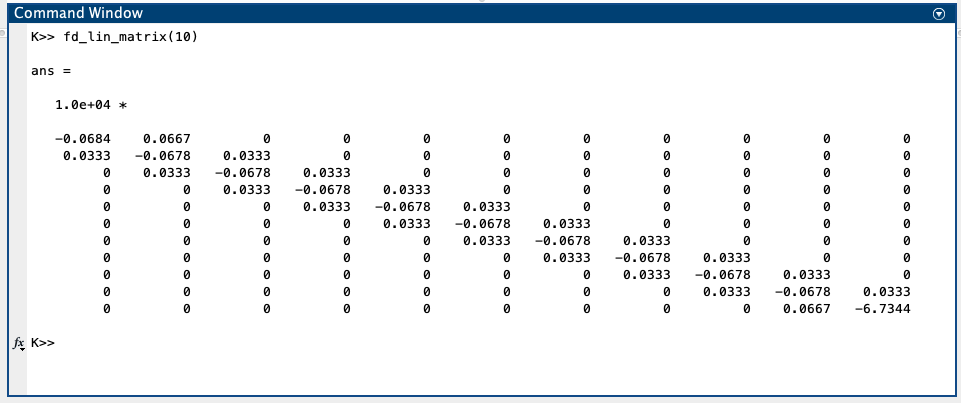

Die Werte sind identisch. 

6.

Im Anhang finden Sie stationaer_lin.m

7.

Damit der Code getstet werden kann, soll man die Defrinzial Gleichung lösen um $u_{\left(z\right)} \;$ Wert zu bestimmen. Da es nicht möglich ist, soll man ein Wert für $u_{\left(z\right)} \;$annehmen.

$u_{\left(z\right)} =z^2 +1$        =>         $\frac{\partial u\left(z\right)}{\partial z }$=2z         =>    $\frac{\partial^2 u\left(z\right)}{\partial z^2 }=2$

D$\frac{\partial^2 u}{\partial z^2 }-\textrm{ku}=-s\left(z\right)$   


$$\left.2D-k{\left(\mathrm{z}\right.}^2 +1\right)=-s\left(z\right)$$



$$s\left(z\right)=-2D+k{\mathrm{z}}^2 +k$$


Von der ersten Randbedingungen :

 D $\frac{\partial u\left(0\right)}{\partial z }$= $S_L$$u\left(0\right)$

 D $\frac{\partial u\left(z\right)}{\partial z }$= $2\textrm{DZ}$ =>   D $\frac{\partial u\left(0\right)}{\partial z }$=0

=> $S_{L\;} u\left(0\right)=0$ => $S_{L\;} *1=0$  

 $S_{L\;} =0$ Während des Tests soll den neuen Wert benutzt.

Von der zweiten Randbedingungen :

 D $\frac{\partial u\left(d\right)}{\partial z }$= ${-S}_R$$u\left(d\right)$

 D $\frac{\partial u\left(d\right)}{\partial z }$= $D\left(2d\right)$         =>          $-S_{R\;} u\left(d\right)=2\textrm{Dd}$   =>    $-S_{R\;} \left(d^2 +1\right)=2\textrm{Dd}$ 


$$S_{R\;} =-\frac{2\;\textrm{Dd}\;}{d^2 +1}$$


Wie in dem folgenden Bild gezeigt, wurde $S_{L\;}$ und $S_{R\;}$ für Test mit neue Werte belegt.

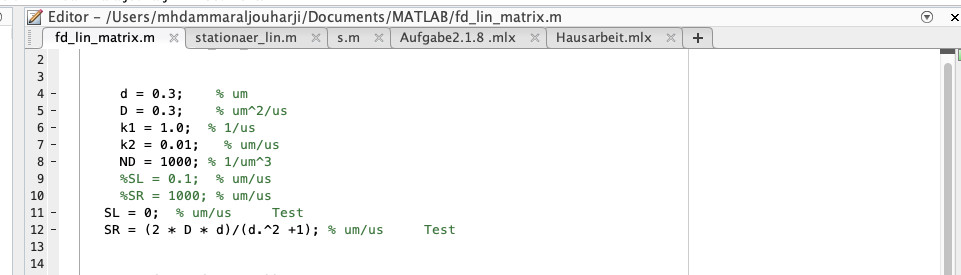

Die Matrix b wurde mit neue $s\left(z\right)=-2D+k{\mathrm{z}}^2 +k$ belegt. Sie finden das in sTestLineare.m

Die Matrix b wurde mit dem Wert N=10 überpruft. 

Der Taschenrechner hat die folgende Ergibnisse gegeben:

$b$ = $-\;s\left(z\right)=-\left(-2D+k{\mathrm{z}}^2 +k\right)$

$b_1$ = $-\;s\left(0\right)=-\left(-2\left(0\ldotp 3\right)+11{\left(0\right)}^2 +11\right)=-10\ldotp 4\;$

$b_2$ = $-\;s\left(0\ldotp 03\right)=-\left(-2\left(0\ldotp 3\right)+11{\left(0\ldotp 03\right)}^2 +11\right)=-10\ldotp 409\;$

$b_3$ = $-\;s\left(0\ldotp 06\right)=-\left(-2\left(0\ldotp 3\right)+11{\left(0\ldotp 06\right)}^2 +11\right)=-10\ldotp 4396\;$ 

Matlab hat die folgende Ergibnisse gegeben:

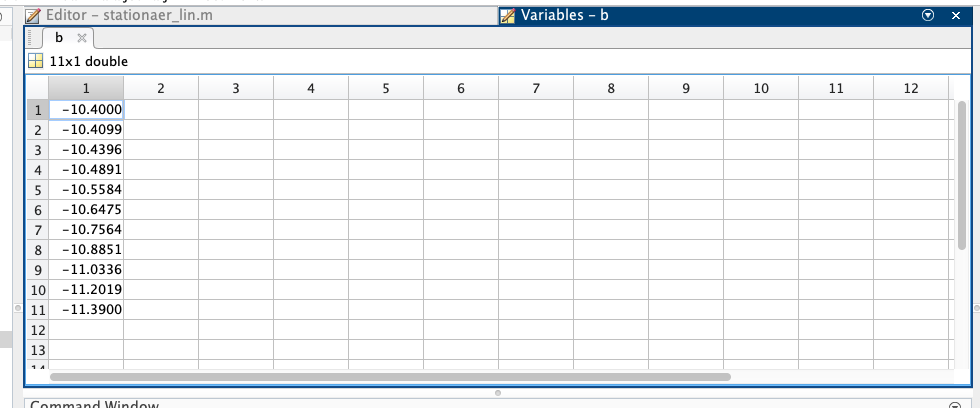

Die Werte sind identisch. 

Es wurde neuene Scripte erstellt heißt fd_lin_matrixTest.m und stationaer_linTest.m .  Dieses fd_lin_matrixTest.m und  fd_lin_matrix.m , stationaer_linTest.m und stationaer_lin.m sind identisch aber fd_lin_matrixTest.m hat neue Werte für SL und SR und  stationaer_linTest.m ruft die sTestLineare.m. 

[z,u]= stationaer_linTest(@sTestLineare,100);
real = z.^2 +1;
N = 100;
TestErgebnisse = zeros(N+1,3); 

for i = 1 : 101
      TestErgebnisse(i ,1 ) = z(i) ;
      TestErgebnisse(i ,2 ) = u(i) ;
      TestErgebnisse(i ,3 ) = real(i) ;
    end
disp (TestErgebnisse) ;

                   0   1.000000000000025   1.000000000000000
   0.003000000000000   1.000009000000025   1.000009000000000
   0.006000000000000   1.000036000000025   1.000036000000000
   0.009000000000000   1.000081000000025   1.000081000000000
   0.012000000000000   1.000144000000025   1.000144000000000
   0.015000000000000   1.000225000000025   1.000225000000000
   0.018000000000000   1.000324000000025   1.000324000000000
   0.021000000000000   1.000441000000025   1.000441000000000
   0.024000000000000   1.000576000000025   1.000576000000000
   0.027000000000000   1.000729000000025   1.000729000000000
   0.030000000000000   1.000900000000025   1.000900000000000
   0.033000000000000   1.001089000000025   1.001089000000000
   0.036000000000000   1.001296000000025   1.001296000000000
   0.039000000000000   1.001521000000025   1.001521000000000
   0.042000000000000   1.001764000000025   1.001764000000000
   0.045000000000000   1.002025000000025   1.002025000000000
   0.048000000000000   1

Hierdamit kann man feststellen, dass die Routine richtig funktioniert.

8.

Für S(z) wurde die s.m erstellt. 

global s0;
N= 1;
Nmax = zeros (1,3);% 3 N für die drei Fälle
x = [10.^4 10.^3 10.^2];
for i= 1 : 3
    N= 1;
    s0 = x(i);
    while 1 == 1
    [z1,u1]=stationaer_lin(@s,N);
    [z2, u2]=stationaer_lin(@s,N*2);
     N=N*2;

  for j = 1: length(z2) 
      for y=1 : length (z1)
        if z1(y) == z2(j)
          relativeFehler(j,1) = (u2(j) - u1(y))/u1(y) ;  
        end
      end
  end
  M=  max (abs (relativeFehler)) ;
  if M < 0.01
      Nmax (i)=N;
      break; % break für whie wenn M < 0.01
  end
  end
end



for i = 1 : 3 
    s0 = x(i) ; 
    [zp,up]=stationaer_lin(@s,Nmax (i));
    plot (zp,up); 
    hold on
    
end
disp (Nmax) ;

    32    32    32



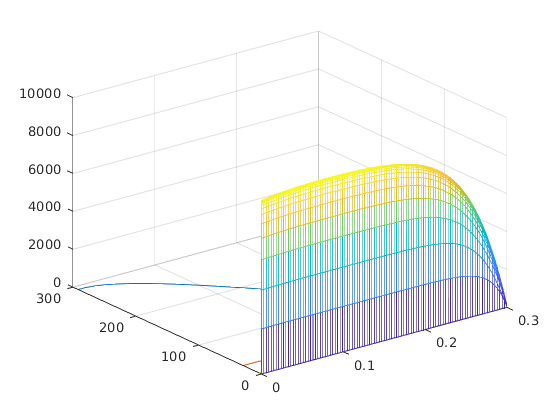

hold off;

______________________________________________________________________________________________________

### 2.2 Nichtlineare stationäre Gleichung

1.

D$\frac{\partial^2 u}{\partial z^2 }-\left(k_1 +k_2 \;N_D \right)\;u-k_2 \;u^2 =-s\left(z\right)$         ,         $0<z<d$

$\frac{\partial u}{\partial z }$ = $\frac{u_{i+1} -u_{i-1} }{2h}$

$\frac{\partial^2 u}{\partial z^2 }$ = $\frac{u_{i+1} -{2u}_i +u_{i-1} }{h^2 }$

D $\left(\frac{u_{i+1} -{2u}_i +u_{i-1} }{h^2 }\right)-\left(k_1 +k_2 \;N_D \right)\;u_i -k_2 \;{u_i }^2 =-s\left(z\right)$

($\frac{D}{h^2 }$) $u_{i-1}$ −  ($\frac{2D}{h^2 }+\left(k_1 +k_2 \;N_D \right)$) $u_i$ + ($\frac{D}{h^2 }$) $u_{i+1\;} -k_2 \;{u_i }^2$ =  $-s\left(z\right)$ 

 $a\;u_{i-1}$ −   ${e\;u}_i$ +  ${c\;u}_{i+1} -g\;u_i^2$ =   $b$                  =>       $a=\frac{D}{h^2 }$      ;      $e=\frac{2D}{h^2 }+\left(k_1 +k_2 \;N_D \right)$     ;  ${g=k}_2$  ;   $c=\frac{D}{h^2 }$ ;   $b$ = $-s\left(z\right)$

Discretize:


$$0<z<d$$
       


$$h=\frac{d-0}{N}=\frac{d}{N}$$



$$i=0,1,2,,,,,,N$$



$$Z_0 =0$$
    
$$Z_N =d$$


Erste Randbedingungen :

 D $\frac{\partial u\left(0\right)}{\partial z }$= $S_L$$u\left(0\right)$

$\frac{\partial u\left(0\right)}{\partial z }$= $\frac{S_L \;u\left(0\right)}{D}$

$\frac{S_L \;u\left(0\right)}{D}$= $\frac{{\mathrm{u}}_{1\;} -u_{-1} }{2h}$

$u\left(0\right)$ = $\frac{{D\;\left(u_1 -u_{-1} \right)}_{\;} }{2h\;S_L }$

$u\left(0\right)$ = $\frac{{D\;}_{\;} }{2h\;S_L }$ $u_1$ −  $\frac{{D\;}_{\;} }{2h\;S_L }$ $u_{-1}$ 

$u_{-1}$  =  $u_1$ −  $\frac{{2h\;S_L }_{\;} }{D}$ $u\left(0\right)$ 

Zweite Randbedingungen :

 D $\frac{\partial u\left(d\right)}{\partial z }$= ${-S}_R$$u\left(d\right)$

$\frac{\partial u\left(d\right)}{\partial z }$= $\frac{{-S}_{R\;} \;u\left(d\right)}{D}$

$\frac{{-S}_{R\;} \;u\left(d\right)}{D}$ = $\frac{{\mathrm{u}}_{N+1} -u_{N-1} }{2h}$

$u\left(d\right)$ = $\frac{D\;\left({\mathrm{u}}_{N+1} -u_{N-1} \right)}{-\;2h\;S_R }$

$u\left(d\right)$ = $\frac{D\;}{-\;2h\;S_R }\;u_{N+1} -\frac{D\;}{-\;2h\;S_R }\;u_{N+1} \;$

$u_{N+1}$= $\frac{-\;2h\;S_R \;}{D}\;u\left(d\right)+\;\;u_{N-1} \;$

$u_{N+1}$= $\frac{-\;2h\;S_R \;}{D}\;u_N +\;\;u_{N-1} \;$

$i=o\Rightarrow$   $a\;u_{-1}$ −   ${e\;u}_0$ +  ${c\;u}_1 -g\;u_0^2$ =   $b$

 $a\left(u_1 -\frac{{2h\;S_L }_{\;} }{D}\;u\left(0\right)\right)$ −   ${e\;u}_0$ +  ${c\;u}_1 -g\;u_0^2$ =   $b$

$au_1 -\frac{{2\;a\;h\;S_L }_{\;} }{D}\;u\left(0\right)$ −   ${e\;u}_0$ +  ${c\;u}_1 -g\;u_0^2$ =   $b$

${\;\left(-\frac{{2\;a\;h\;S_L }_{\;} }{D}-e\;\right)u_o }$ +  ${\left(a+c\right)\;\;u}_1 -g\;u_0^2$ =   $b$   wenn  $Z=0$ ist.

$i=N\Rightarrow$   $a\;u_{N-1}$ −   ${e\;u}_N$ +  ${c\;u}_{N+1} -g\;u_N^2$ =   $b$

$a\;u_{N-1}$ −   ${e\;u}_N$ +  ${c\;\left(\frac{-\;2h\;S_R \;}{D}\;u_N +\;\;u_{N-1} \;\right)-g\;u_N^2 }$ =   $b$

$a\;u_{N-1}$ −   ${e\;u}_N$ −   ${\frac{\;2\;c\;h\;S_R \;}{D}\;u_N +\;\;{c\;u}_{N-1} -g\;u_N^2 } \;$ =   $b$

$\left(a+c\right)\;u_{N-1}$  −   ( ${e\;}$ +   ${\frac{\;2\;c\;h\;S_R \;}{D}\;}$)$u_N -g\;u_N^2$  =   $b$  wenn  $Z=d$ ist.

$f (u)=   \pmatrix{ ((\frac{-2ahS_l}{D} )-e)u_0 + (a+c)u_1 - g u_0^2\cr a u_{i-1} -e u_i + c u_{i+1} - g u_i^2    \cr (a+c)u_{N-1} - (e + \frac{2chS_R}{D}  ) u_N - g u_N^2  }$ =b

2.

Im Anhang finden Sie fd_nonlin.m

3.


$$\frac{\partial f_0 }{\partial {u_0 } }=\left(-\frac{{2\;a\;h\;S_L }_{\;} }{D}-e\;\right)-2g\;u_0$$



$$\frac{\partial f_0 }{\partial {u_1 } }=a+c$$



$$\frac{\partial f_i }{\partial {u_{i-1} } }=a$$



$$\frac{\partial f_i }{\partial {u_i } }=-e-2g\;u_i$$



$$\frac{\partial f_i }{\partial {u_{i+1} } }=c$$



$$\frac{\partial f_d }{\partial {u_{N-1} } }=\left(a+c\right)$$



$$\frac{\partial f_d }{\partial {u_N } }=-\left(e+\frac{2{\textrm{chS}}_R }{D}\right)-2\;g\;u_N$$
 


$$Df =   \pmatrix{(\frac{-2ahS_L}{D} -e -2g u_0 )& (a+ c)  \cr & &a & (-e -2 g u_1)&c  \cr  &&&&& .. & ..&..  \cr &&&&&&&& .. & ..&..  \cr  &&&&&&&&&&&a & (-e -2 g u_{N-1})&c \cr &&&&&&&&&&&&&& (a+c) & -(\frac{e + 2chS_R}{D})-2 gu_N    }$$


4.

Im Anhang finden Sie fd_nonlin_jac.m .

5.

Im Anhang finden Sie stationaer_nonlin.m

Um newton.m zu benutzen wurde die Funktion handle f.m erstelt, um die Funktionen von fd_nonlin_jac.m und fd_nonlin.m an newton.m in ein Praramiter zu schicken.

6.

Damit der Code getstet werden kann, soll man die Defrinzial Gleichung lösen um $u_{\left(z\right)} \;$ Wert zu bestimmen. Da es nicht möglich ist, soll man ein Wert für $u_{\left(z\right)} \;$annehmen.

$u_{\left(z\right)} =z^2 +1$        =>         $\frac{\partial u\left(z\right)}{\partial z }$=2z         =>    $\frac{\partial^2 u\left(z\right)}{\partial z^2 }=2$

D$\frac{\partial^2 u}{\partial z^2 }-\left(k_1 +k_2 \;N_D \right)\;u-k_2 \;u^2 =-s\left(z\right)$         ,         $0<z<d$

D$\frac{\partial^2 u}{\partial z^2 }-\left(k_1 +k_2 \;N_D \right)\;u-k_2 \;u^2 =-s\left(z\right)$         


$$\left.2D-\left(k_1 +k_2 \;N_D \right)\;{\left(\mathrm{z}\right.}^2 +1\right)\;-k_{2\;} \left(z^2 +1\right)=-s\left(z\right)$$



$$s\left(z\right)=-2D+k_1 {\mathrm{z}}^2 +k_2 N_D {\mathrm{z}}^2 +k_1 +k_2 \;N_D +k_2 {\mathrm{z}}^2 +k_2$$


Von der ersten Randbedingungen :

 D $\frac{\partial u\left(0\right)}{\partial z }$= $S_L$$u\left(0\right)$

 D $\frac{\partial u\left(z\right)}{\partial z }$= $2\textrm{DZ}$ =>   D $\frac{\partial u\left(0\right)}{\partial z }$=0

=> $S_{L\;} u\left(0\right)=0$ => $S_{L\;} *1=0$  

 $S_{L\;} =0$ Während des Tests soll den neuen Wert benutzt.

Von der zweiten Randbedingungen :

 D $\frac{\partial u\left(d\right)}{\partial z }$= ${-S}_R$$u\left(d\right)$

 D $\frac{\partial u\left(d\right)}{\partial z }$= $D\left(2d\right)$         =>          $-S_{R\;} u\left(d\right)=2\textrm{Dd}$   =>    $-S_{R\;} \left(d^2 +1\right)=2\textrm{Dd}$ 


$$S_{R\;} =-\frac{2\;\textrm{Dd}\;}{d^2 +1}$$


Wie in der Aufgabe 2.1.7. wurde es neue Scripte für Test Verfahren erstellt. "fd_nonlinTest.m + fd_nonlinjacTest.m + fTest.m + sTestNichtlinear.m".

[z,u]=stationaer_nonlinTest(@sTestNichtlinear,100,10.^-10,1000);
real = z.^2 +1;
TestErgebnisse = zeros(101,3); 

for i = 1 : 101
      TestErgebnisse(i ,1 ) = z(i) ;
      TestErgebnisse(i ,2 ) = u(i) ;
      TestErgebnisse(i ,3 ) = real(i) ;
    end
disp (TestErgebnisse) ;

                   0   0.999978288641126   1.000000000000000
   0.003000000000000   0.999987285052239   1.000009000000000
   0.006000000000000   1.000014274287089   1.000036000000000
   0.009000000000000   1.000059256350220   1.000081000000000
   0.012000000000000   1.000122231249200   1.000144000000000
   0.015000000000000   1.000203198994636   1.000225000000000
   0.018000000000000   1.000302159600172   1.000324000000000
   0.021000000000000   1.000419113082500   1.000441000000000
   0.024000000000000   1.000554059461365   1.000576000000000
   0.027000000000000   1.000706998759579   1.000729000000000
   0.030000000000000   1.000877931003034   1.000900000000000
   0.033000000000000   1.001066856220711   1.001089000000000
   0.036000000000000   1.001273774444695   1.001296000000000
   0.039000000000000   1.001498685710197   1.001521000000000
   0.042000000000000   1.001741590055570   1.001764000000000
   0.045000000000000   1.002002487522324   1.002025000000000
   0.048000000000000   1

Hiermit kann man feststellen, dass die Routine richtig funktionniert.

7.

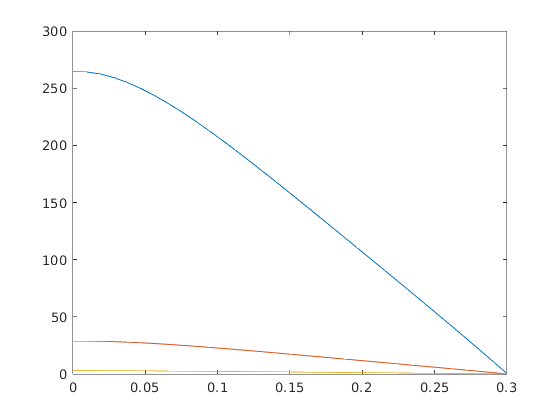

  global s0;
N= 1;
Nmax = zeros (1,3);% 3 N für die drei Fälle
x = [10.^4 10.^3 10.^2];
for i= 1 : 3
    N= 1;
    s0 = x(i);
    while 1 == 1
        
        
   [z1,u1]=stationaer_nonlin(@s,N,10.^-10,1000);
   [z2,u2]=stationaer_nonlin(@s,N*2,10.^-10,1000);
  
    
    
    
     N=N*2;
  
  for j = 1: length(z2) 
      for y=1 : length (z1)
        if z1(y) == z2(j)
          relativeFehler(j,1) = (u2(j) - u1(y))/u1(y) ;  
        end
      end
  end
  M=  max (abs (relativeFehler)) ;
  if M < 0.01
      Nmax (i)=N;
   
      break; % break für whie wenn M < 0.01
%plot (z1,u1); 
  end
  end
end
for i = 1 : 3 
    s0 = x(i) ; 
           
   [z1,u1]=stationaer_nonlin(@s,Nmax(i),10.^-10,1000);
   plot (z1,u1); 
   hold on
    
end

 hold off;



  disp (Nmax) ;

    32    32    32



## 3 Implizite Einschrittverfahren - Leonard Berresheim

tol = 10^(-10)

tol =      1.000000000000000e-10


nmax = 100;

### 3.1 Entwicklung

1. Bei einer steifen Differenzialgleichung handelt es sich um eine Gleichung, für die gilt, dass bei bestimmten numerischen Methoden der Störfaktor am Ausgang besonders groß ist, wenn die Schrittweite nicht sehr klein gewählt wird.

2. Geben sind das implizite Euler-Verfahren


$${\mathbf{y}}^{\left(i+1\right)} ={\mathbf{y}}^{\left(i\right)} +h\;\mathbf{f}\left(t_{i+1} ,{\mathbf{y}}^{\left(i+1\right)} \right)\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(a\ldotp 1\right)$$


und die implizite Trapezregel


$${\mathbf{y}}^{\left(i+1\right)} ={\mathbf{y}}^{\left(i\right)} +\frac{h}{2}\;\left\lbrack \mathbf{f}\left(t_i ,{\mathbf{y}}^{\left(i\right)} \right)+\mathbf{f}\left(t_{i+1} ,{\mathbf{y}}^{\left(i+1\right)} \right)\right\rbrack \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(a\ldotp 2\right)$$


Wir setzten nun


$${\mathbf{y}}^{\left(i+1\right)} ={\mathbf{y}}^{\left(i\right)} +\mathbf{z}\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(a\ldotp 3\right)$$


ein in $\left(a\ldotp 1\right)$


$${\mathbf{y}}^{\left(i\right)} +\mathbf{z}={\mathbf{y}}^{\left(i\right)} +h\;\mathbf{f}\left(t_{i+1} ,{\mathbf{y}}^{\left(i\right)} +\mathbf{z}\right)\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(a\ldotp 4\right)\;$$


und in $\left(a\ldotp 2\right)$


$${\mathbf{y}}^{\left(i\right)} +\mathbf{z}={\mathbf{y}}^{\left(i\right)} +\frac{h}{2}\;\left\lbrack \mathbf{f}\left(t_i ,{\mathbf{y}}^{\left(i\right)} \right)+\mathbf{f}\left(t_{i+1} ,{\mathbf{y}}^{\left(i\right)} +\mathbf{z}\right)\right\rbrack \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(a\ldotp 5\right)\;$$


Formulieren wir nun beides als Nullstellenproblem für $\mathbf{z}$ erhalten wir


$${\mathbf{F}}_{\textrm{euler}} \left(\mathbf{z}\right)=h\;\mathbf{f}\left(t_{i+1} ,{\mathbf{y}}^{\left(i\right)} +\mathbf{z}\right)-\mathbf{z}\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(a\ldotp 6\right)\;\;\;$$


und


$${\mathbf{F}}_{\textrm{trapez}} \left(\mathbf{z}\right)=\frac{h}{2}\;\left\lbrack \mathbf{f}\left(t_i ,{\mathbf{y}}^{\left(i\right)} \right)+\mathbf{f}\left(t_{i+1} ,{\mathbf{y}}^{\left(i\right)} +\mathbf{z}\right)\right\rbrack -\mathbf{z}\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(a\ldotp 7\right)\;\;\;$$


3. Die Jacobi-Matrix in Abhängigkeit von $D_y \mathbf{f}$ sieht wie folgt aus


$${D\;\mathbf{F}}_{\textrm{euler}} \left(\mathbf{z}\right)={h\;D}_{\left(y\right)} \mathbf{f}\left(t_{i+1} ,y^{\left(i\right)} +z\right)-\overset{~}{D} \mathbf{z}\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(a\ldotp 8\right)$$


für das implizite Euler-Verfahren und


$${D\;\mathbf{F}}_{\textrm{euler}} \left(\mathbf{z}\right)=\frac{h}{2}\left\lbrack {\;D}_{\left(y\right)} \mathbf{f}\left(t_i ,y^{\left(i\right)} \right)+{h\;D}_{\left(y\right)} \mathbf{f}\left(t_{i+1} ,y^{\left(i\right)} +z\right)\right\rbrack -\overset{~}{D} \mathbf{z}\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(a\ldotp 9\right)$$


für das implizite Trapez-Verfahren,

wobei


$$D_y \mathbf{f}=\left\lbrack \begin{array}{cccc}
\frac{\partial f_1 }{\partial y_1 } & \frac{\partial f_1 }{\partial y_2 } & \cdots  & \frac{\partial f_1 }{\partial y_n }\\
\frac{\partial f_2 }{\partial y_1 } & \frac{\partial f_2 }{\partial y_2 } & \cdots  & \frac{\partial f_2 }{\partial y_n }\\
\vdots  & \vdots  & \; & \vdots \\
\frac{\partial f_n }{\partial y_1 } & \frac{\partial f_n }{\partial y_2 } & \cdots  & \frac{\partial f_n }{\partial y_n }
\end{array}\right\rbrack \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(a\ldotp 10\right)$$


und 


$$\overset{~}{D} \mathbf{z}=\left\lbrack \begin{array}{cccc}
1 & 0 & \cdots  & 0\\
0 & 1 & \ddots  & \vdots \\
\vdots  & \ddots  & \ddots  & 0\\
0 & \cdots  & 0 & 1
\end{array}\right\rbrack \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(a\ldotp 11\right)$$


4. Die Routinen **F_euler** & **F_trapez** wurden implementiert

*(siehe F_euler.m & F_trapez.m)*

5. Die Routinen **impl_euler** & **impl_trapez **wurden implementiert

*(siehe impl_euler.m & impl_trapez.m)*

6. Sei das Anfangswertproblem


$$y^{\prime } =-y\;\textrm{mit}\;y\left(0\right)=1\;\textrm{und}\;t\in \left\lbrack 0,1\right\rbrack \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(b\ldotp 1\right)$$


Mit Hilfe von Wolframalpha ehällte man für $\left(b\ldotp 1\right)$ die Lösung


$$y^{\prime } \left(x\right)={c_1 e}^{-x} \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(b\ldotp 2\right)$$


Es wurde die Routine **max_abs_err **implementiert um für eine bestimmte Funktion und einen bestimmten Wert für **n** den maximalen absoluten Fehler zu bestimmen.

*(siehe max_abs_err.m)*

Diese Routine wird nun auf $\left(b\ldotp 1\right)$ angewendet um die Ordnung der beiden Verfahren (Euler & Trapez) zu bestimmen.

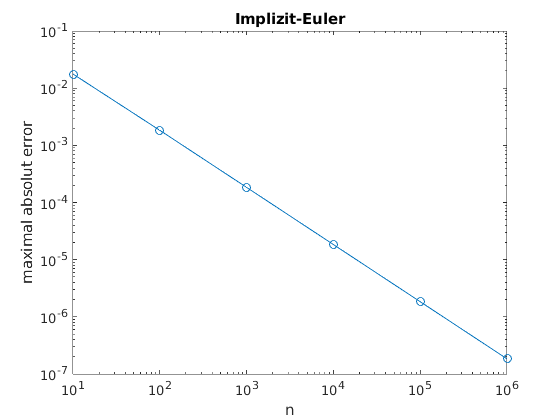

tspan = [0,1];
n= 10.^(1:6);
ya = 1;
f = @(t,y) -y;
df = @(t,y) -1;
f_loesung = @(x) exp(-x);
max_error = max_abs_err(@(n) impl_euler(f,tspan,ya,n,df,tol,nmax), n, f_loesung);
loglog(n, max_error, "-o")
title("Implizit-Euler")
xlabel("n")
ylabel("maximal absolut error")

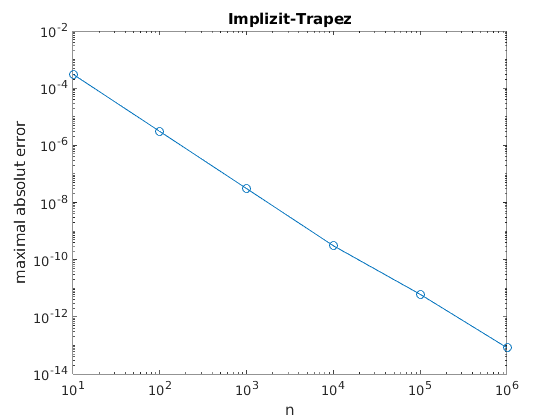

max_error = max_abs_err(@(n) impl_trapez(f,tspan,ya,n,df,tol,nmax), n, f_loesung);
loglog(n, max_error, "-o")
title("Implizit-Trapez")
xlabel("n")
ylabel("maximal absolut error")

7. Wir testen nun die Routinen **F_euler **und **F_trapez** mit folgendem System von Anfangswertproblemen


$${\mathbf{y}}^{\prime } =\left\lbrack \begin{array}{c}
t\;y_1 -3y_2 \\
3y_1 -t^2 y_2 
\end{array}\right\rbrack ;\mathbf{y}\left(0\right)=\left\lbrack \begin{array}{c}
2\\
1
\end{array}\right\rbrack ;t=\left\lbrack 0,10\right\rbrack ;h=1\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(c\ldotp 1\right)$$


Um zu bestimmen ob die Routinen richtige Ergebnisse liefern, wird als referenz Lösung die von Matlab bereitgestellte Routine ode45 verwendet.

n = 10^(2);
tspan = [0,1]

tspan =      0     1


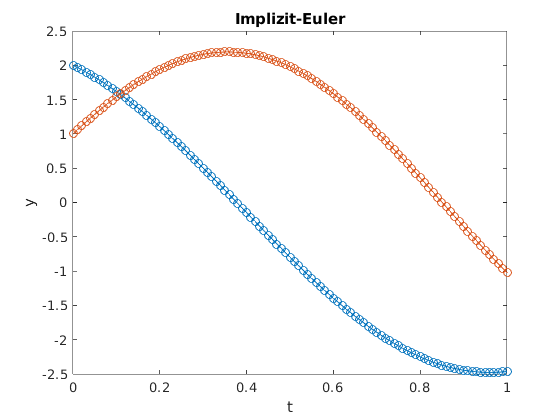

ya = [2;1];
f = @(t,y) [t*y(1)-3*y(2);3*y(1)-((t^2)*y(2))];
df = @(t,y) [t,-3;3,-(t^2)];
[t,y_out] = impl_euler(f,tspan,ya,n,df,tol,nmax);
plot(t,y_out, '-o')
title("Implizit-Euler")
xlabel("t")
ylabel("y")

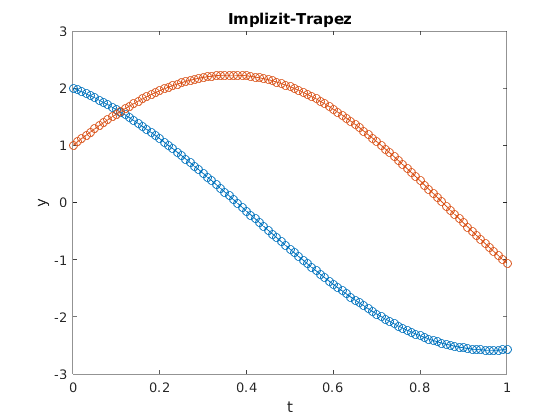

[t,y_out] = impl_trapez(f,tspan,ya,n,df,tol,nmax);
plot(t,y_out, '-o')
title("Implizit-Trapez")
xlabel("t")
ylabel("y")

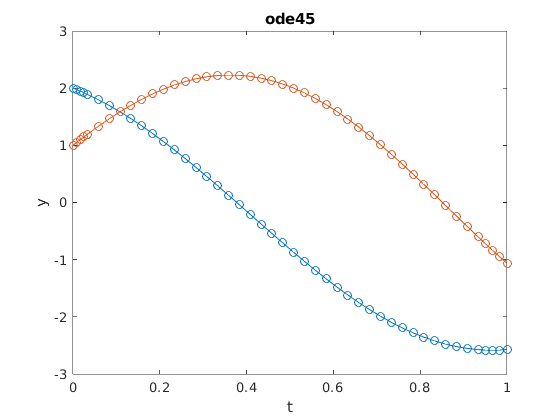

[t,y_out] = ode45(f,tspan,ya);
plot(t,y_out, '-o')
title("ode45")
xlabel("t")
ylabel("y")

### 3.2 Anwendung

1. Wir formulieren die Gleichung (9) aus der Aufgabenstellung  als


$${\mathbf{y}}^{\prime } =\mathbf{f}\left(t,\mathbf{y}\right)=\left\lbrack \begin{array}{c}
-0\ldotp 04y_1 +{10}^4 y_2 y_3 \\
0\ldotp 04y_1 -{10}^4 y_2 y_3 -3\cdot {10}^7 y_2^2 \\
3\cdot {10}^7 y_2^2 
\end{array}\right\rbrack \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(f\ldotp 1\right)\;\;\;\;$$


mit $t\in \left\lbrack 0,~\right\rbrack ,\;\mathbf{y}\left(0\right)=\left\lbrack \begin{array}{c}
1\\
0\\
0
\end{array}\right\rbrack \;$

2. Es wurde nun **f_chem** implementiert

*(siehe f_chem.m)*

3. Es wird die Jacobi-Matrix von ${\mathbf{f}}_{\textrm{chem}}$bezüglich $\mathbf{y}$ berechnet:


$$D_y {\mathbf{f}}_{\textrm{chem}} \left(t,y\right)=\left\lbrack \begin{array}{ccc}
-0\ldotp 04 & {10}^4 y_3  & {10}^4 y_2 \\
0\ldotp 04 & -{10}^4 y_3 -6\cdot {10}^7 y_2  & -{10}^4 y_2 \\
0 & 3\cdot {10}^7  & 0
\end{array}\right\rbrack \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(f\ldotp 2\right)$$


4. Es wurde **f_chem_jac **implementiert

*(siehe f_chem_jac.m)*

5. Wir berechnung nun für jedes Verfahren ein geeigneten Wert für n, sodass der maximale absolute Fehler bei höchsten ${10}^{-4}$ bzw. ${10}^{-6}$ liegt. Dafür wurde die Routine **max_abs_error2** implementiert, in der die jeweiligen **y-**Werte mit den **y**-Werte des selben Verfahren mit einem Wert n*10 verglichen (dieses dient als Referenzlösung). 

*(siehe max_abs_error2.m)*

tspan = [0,1];
ya = [1;0;0];
f = @(t,y) [-0.04*y(1)+10^4*y(2)*y(3);
           0.04*y(1)-10^4*y(2)*y(3)-3*10^7*y(2)^2;
           3*10^7*y(2)^2];

Explizit Euler:

n_eeuler_4 = 1073;
max_error = max_abs_error2(@(n) euler_verfahren(@f_chem,tspan,ya,n),n_eeuler_4)

max_error =      9.702635541052052e-05


n_eeuler_6 = 7040;
max_error = max_abs_error2(@(n) euler_verfahren(@f_chem,tspan,ya,n),n_eeuler_6)

max_error =      9.999324648256923e-07


Mittelpunkt:

n_mittelpunkt_4 = 639;
max_error = max_abs_error2(@(n) mittelpunkt(@f_chem,tspan,ya,n),n_mittelpunkt_4)

max_error =      9.879407975250248e-05


n_mittelpunkt_6 = 2121;
max_error = max_abs_error2(@(n) mittelpunkt(@f_chem,tspan,ya,n),n_mittelpunkt_6)

max_error =      9.997975050485095e-07


Implizit Euler:

n_ieuler_4 = 10000;%407
max_error = max_abs_error2(@(n) impl_euler(@f_chem,tspan,ya,n,@f_chem_jac,tol,nmax),n_ieuler_4)

max_error =      6.380903357648420e-07


n_ieuler_6 = 6243;
max_error = max_abs_error2(@(n) impl_euler(@f_chem,tspan,ya,n,@f_chem_jac,tol,nmax),n_ieuler_6)

max_error =      9.998457963878206e-07


Implizit Trapez:

n_trapez_4 = 378;
max_error = max_abs_error2(@(n) impl_trapez(@f_chem,tspan,ya,n,@f_chem_jac,tol,nmax),n_trapez_4)

max_error =      9.916737320489377e-05


n_trapez_6 = 1310;
max_error = max_abs_error2(@(n) impl_trapez(@f_chem,tspan,ya,n,@f_chem_jac,tol,nmax),n_trapez_6)

max_error =      9.998179942015608e-07


Aus den Ergebnissen erstellen wir folgende Tabelle

verfahren = {'';'explizit euler';'mittelpunkt';'implizit euler';'implizit trapez'};
fehlerGroesser = [10^(-4);n_eeuler_4;n_mittelpunkt_4;n_ieuler_4;n_trapez_4]; 
fehlerGreosser = [10^(-6);n_eeuler_6;n_mittelpunkt_6;n_ieuler_6;n_trapez_6];
T = table(verfahren, fehlerGroesser, fehlerGreosser)

T = 5×3 table
         verfahren         fehlerGroesser    fehlerGreosser
    ___________________    ______________    ______________

    {0×0 char         }        0.0001            1e-06     
    {'explizit euler' }          1073             7040     
    {'mittelpunkt'    }           639             2121     
    {'implizit euler' }         10000             6243     
    {'implizit trapez'}           378             1310     


6. Aus den Ergebnissen der vorrigen Aufgabe lässt sich schließen, dass wenn der absolute Fehler bei höchstens ${10}^{-4}$ liegen soll, die beiden impliziten Verfahren am perfomanz stärksten sind.

Soll der absolute Fehler jedoch höchstens ${10}^{-6}$ betragen, erweist sich das mittelpunkt Verfahren als perfomanter als das implizite Euler-Verfahren. Das implizite Trapez-Verfahren bleibt jedoch auf Platz Uno.

### 4. Zeitaufgelöste Simulation - MHD Ammar Aljouharji und Leonard Berresheim

1. 


$$u_0 =F\left(t,u\right)\ldotp$$



$$\frac{\partial u}{\partial t}\left(t,z_i \right)=D\frac{\partial^2 u}{\partial z^2 }\left(t,z_i \right)-\left(k_1 +k_2 \textrm{ND}\right)u\left(t,z_i \right)-k_2 u^2 \left(t,z_i \right)+s\left(t,z_i \right),t\ge 0,i=0,1,\ldotp \ldotp \ldotp ,N$$


$\frac{\partial u}{\partial z }$ = $\frac{u_{i+1} -u_{i-1} }{2h}$

$\frac{\partial^2 u}{\partial z^2 }$ = $\frac{u_{i+1} -{2u}_i +u_{i-1} }{h^2 }$


$$\frac{\partial u}{\partial t}\left(t,z_i \right)=D\left(\frac{u_{i+1} \left(t,z_{i+1} \right)-{2u}_i \left(t,z_i \right)+u_{i-1} \left(t,z_{i-1} \right)}{h^2 }\right)-\left(k_1 +k_2 \textrm{ND}\right)u_i \left(t,z_i \right)-k_2 u_i^2 \left(t,z_i \right)+s\left(t,z_i \right)$$


$\frac{\partial u}{\partial t}\left(t,z_i \right)=$($\frac{D}{h^2 }$) $u_{i-1} \left(t,z_{i-1} \right)$ −  ($\frac{2D}{h^2 }+\left(k_1 +k_2 \;N_D \right)$) $u_i \left(t,z_i \right)$ + ($\frac{D}{h^2 }$) $u_{i+1\;} \left(t,z_{i+1} \right)-k_2 \;{u_i }^2 \left(t,z_i \right)+s\left(t,z_i \right)$  

 $\frac{\partial u}{\partial t}\left(t,z_i \right)=a\;u_{i-1}$$\left(t,z_{i-1} \right)$ −   ${e\;u}_i \left(t,z_i \right)$ +  ${c\;u}_{i+1} \left(t,z_{i+1} \right)-g\;u_i^2$$\left(t,z_i \right)$ +  $b$   

               =>       $a=\frac{D}{h^2 }$      ;      $e=\frac{2D}{h^2 }+\left(k_1 +k_2 \;N_D \right)$     ;  ${g=k}_2$  ;   $c=\frac{D}{h^2 }$ ;   $b$ = $s\left(t,z_i \right)$

Discretize:


$$0<z<d$$
       


$$h=\frac{d-0}{N}=\frac{d}{N}$$



$$i=0,1,2,,,,,,N$$



$$Z_0 =0$$
    
$$Z_N =d$$


Erste Randbedingungen :

 D $\frac{\partial u\left(0\right)}{\partial z }$= $S_L$$u\left(0\right)$

$\frac{\partial u\left(0\right)}{\partial z }$= $\frac{S_L \;u\left(0\right)}{D}$

$\frac{S_L \;u\left(0\right)}{D}$= $\frac{{\mathrm{u}}_{1\;} \left(t,z_1 \right)-u_{-1} \left(t,z_{-1} \right)}{2h}$

$u\left(0\right)$ = $\frac{{D\;\left(u_1 \left(t,z_1 \right)-u_{-1} \left(t,z_{-1} \right)\right)}_{\;} }{2h\;S_L }$

$u\left(0\right)$ = $\frac{{D\;}_{\;} }{2h\;S_L }$ $u_1$$\left(t,z_1 \right)$ −  $\frac{{D\;}_{\;} }{2h\;S_L }$ $u_{-1} \left(t,z_{-1} \right)$ 

$u_{-1} \left(t,z_{-1} \right)$  =  $u_1 \left(t,z_1 \right)$ −  $\frac{{2h\;S_L }_{\;} }{D}$ $u\left(0\right)$ 

Zweite Randbedingungen :

 D $\frac{\partial u\left(d\right)}{\partial z }$= ${-S}_R$$u\left(d\right)$

$\frac{\partial u\left(d\right)}{\partial z }$= $\frac{{-S}_{R\;} \;u\left(d\right)}{D}$

$\frac{{-S}_{R\;} \;u\left(d\right)}{D}$ = $\frac{{\mathrm{u}}_{N+1} \left(t,z_{N+1} \right)-u_{N-1} \left(t,z_{N-1} \right)}{2h}$

$u\left(d\right)$ = $\frac{D\;\left({\mathrm{u}}_{N+1} \left(t,z_{N+1} \right)-u_{N-1} \left(t,z_{N-1} \right)\right)}{-\;2h\;S_R }$

$u\left(d\right)$ = $\frac{D\;}{-\;2h\;S_R }\;u_{N+1} \left(t,z_{N+1} \right)-\frac{D\;}{-\;2h\;S_R }\;u_{N+1} \left(t,z_{N+1} \right)\;$

$u_{N+1} \left(t,z_{N+1} \right)$= $\frac{-\;2h\;S_R \;}{D}\;u\left(d\right)+\;\;u_{N-1} \left(t,z_{N+1} \right)\;$

$u_{N+1} \left(t,z_{N+1} \right)$= $\frac{-\;2h\;S_R \;}{D}\;u_N +\;\;u_{N-1} \left(t,z_{N-1} \right)\;$

$i=o\Rightarrow$   $\frac{\partial u}{\partial t}\left(t,z_0 \right)=a\;u_{-1}$$\left(t,z_{-1} \right)$ −   ${e\;u}_0 \left(t,z_0 \right)$ +  ${c\;u}_1 \left(t,z_1 \right)-g\;u_0^2$$\left(t,z_0 \right)$ +  $b$

 $\frac{\partial u}{\partial t}\left(t,z_0 \right)=a\left(u_1 \left(t,z_1 \right)-\frac{{2h\;S_L }_{\;} }{D}\;u\left(0\right)\right)$ −   ${e\;u}_0 \left(t,z_0 \right)$ +  ${c\;u}_1 \left(t,z_1 \right)-g\;u_0^2$$\left(t,z_0 \right)$ +  $b$

${\frac{\partial u}{\partial t}\left(t,z_0 \right)=\;\left(-\frac{{2\;a\;h\;S_L }_{\;} }{D}-e\;\right)u_o \left(t,z_0 \right)}$ +  ${\left(a+c\right)\;\;u}_1 \left(t,z_1 \right)-g\;u_0^2 \left(t,z_0 \right)+b$ 

wenn  $Z=0$ ist.

$i=N\Rightarrow$ $\frac{\partial u}{\partial t}\left(t,z_N \right)=a\;u_{N-1}$$\left(t,z_{N-1} \right)$ −   ${e\;u}_N \left(t,z_N \right)$ +  ${c\;u}_{N+1} \left(t,z_{N+1} \right)-g\;u_N^2$$\left(t,z_N \right)$ +  $b$  

$\frac{\partial u}{\partial t}\left(t,z_N \right)=$$a\;u_{N-1}$$\left(t,z_{N-1} \right)$ −   ${e\;u}_N$$\left(t,z_N \right)$ +  ${c\;\left(\frac{-\;2h\;S_R \;}{D}\;u_N \left(t,z_N \right)+\;\;u_{N-1} \;\left(t,z_{N-1} \right)\right)-g\;u_N^2 \left(t,z_N \right)}$+  $b$

$\frac{\partial u}{\partial t}\left(t,z_N \right)=\left(a+c\right)\;u_{N-1} \left(t,z_{N-1} \right)$  −   ( ${e\;}$ +   ${\frac{\;2\;c\;h\;S_R \;}{D}\;}$)$u_N \left(t,z_N \right)-g\;u_N^2 \left(t,z_N \right)$ +  $b$  

wenn  $Z=d$ ist.

$f (t,u)=   \pmatrix{ ((\frac{-2ahS_l}{D} )-e)u_0(t,z_0) + (a+c)u_1(t,z_1) - g u_0^2(t,z_0) + b \cr a u_{i-1}(t,z_{i-1}) -e u_i(t,z_{i}) + c u_{i+1} (t,z_{i+1})- g u_i^2(t,z_{i}) +b   \cr (a+c)u_{N-1} (t,z_{N-1})- (e + \frac{2chS_R}{D}  ) u_N (t,z_{N})- g u_N^2 (t,z_{i-1})(t,z_{N}) +b }$ =$\frac{\partial u}{\partial t}\left(t,z_i \right)$

Jacobi Matrix dafür ist 


$$Df =   \pmatrix{(\frac{-2ahS_L}{D} -e -2g u_0(t,z_{0})  )& (a+ c)  \cr & &a & (-e -2 g u_1(t,z_{1}) )&c  \cr  &&&&& .. & ..&..  \cr &&&&&&&& .. & ..&..  \cr  &&&&&&&&&&&a & (-e -2 g u_{N-1}(t,z_{N-1}) )&c \cr &&&&&&&&&&&&&& (a+c) & -(\frac{e + 2chS_R}{D})-2 gu_N(t,z_{N})     }$$


2. 

3. Es wird die implizit Trapezregel angewendet auf das System


$$\frac{\partial u}{\partial t}\left(t,z_i \right)=D\frac{\partial^2 u}{\partial z^2 }\left(t,z_i \right)-\left(k_1 +k_2 N_D \right)u\left(t,z_i \right)-k_2 u^2 \left(t,z_i \right)+s\left(t,z_i \right)\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(z\ldotp 1\right)$$


mit


$$i=0,1,\ldotp \ldotp \ldotp ,N\;\;\;,\;\;\;\;t\in \left\lbrack -0\ldotp 05,0\ldotp 2\right\rbrack \mu s$$


und


$$s\left(t,z\right)=S_0 \cdot e^{-\frac{t^2 }{2\cdot 0\ldotp {01}^2 }} \cdot e^{-a\;z} ,\;\;\;S_0 ={10}^4 ,{10}^5 ,{10}^6 \frac{1}{\mu m^3 \mu s}\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;$$
    

und


$$u\left(t_0 ,z\right)=0$$


Wir wählen als Ortsinterval


$$n_y =100$$


und als Zeitinterval


$$n_t =100$$


global s0;
tspan = [0,0.25];
n_t = 100;
n_y = 100;
ya = zeros(n_y+1,1);
z = linspace(0,0.3,n_y+1);

s0 = 10^4;
[t1,y1] = impl_trapez(@fd_nonlinearZeit,tspan,ya,n_t,@fd_nonlinearZeit_jac,tol,nmax);
s0 = 10^5;
[t2,y2] = impl_trapez(@fd_nonlinearZeit,tspan,ya,n_t,@fd_nonlinearZeit_jac,tol,nmax);
s0 = 10^6;
[t3,y3] = impl_trapez(@fd_nonlinearZeit,tspan,ya,n_t,@fd_nonlinearZeit_jac,tol,nmax);

4. Die Ergebnisse werden mit Hilfe von **mesh** geeignet dargestellt

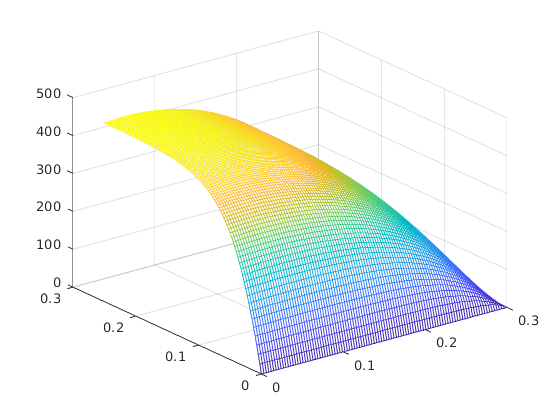

figure;
mesh(z,t1,y1);

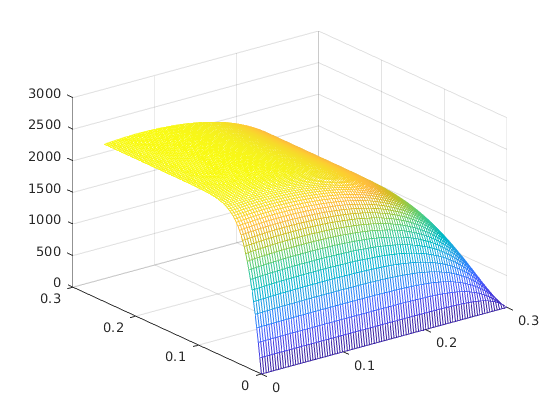


figure;
mesh(z,t2,y2);

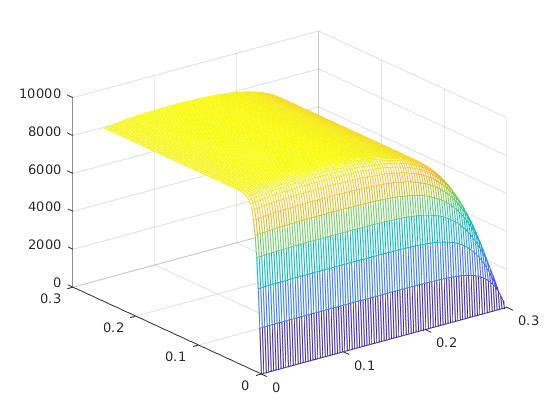


figure;
mesh(z,t3,y3);